# Problema 8

function [R, a, b] = pade_approximation(coeff, m, k, x)
    % Asigurăm lungimea corectă a coeficienților Maclaurin
    required_length = m + k + 1;
    
    if length(coeff) < required_length
        error('Vectorul coeff nu are suficienti termeni.');
    end

    % Construim matricea sistemului liniar pentru b
    C = zeros(k,k);
    for row = 1:k
        idx_start = m + row;
        idx_end = max(1, m + row - k + 1);
        C(row,:) = coeff(idx_start:-1:idx_end);
    end

    d = -coeff(m+1:m+k)';  % Partea dreaptă a sistemului

    % Rezolvăm sistemul pentru b
    b = C\d;
    b = [1; b]; % Adăugăm b0 = 1

    % Calculăm coeficienții a_i
    a = zeros(m+1,1);
    for j = 0:m
        sum_ab = 0;
        for ell = 0:min(j,k)
            sum_ab = sum_ab + coeff(j-ell+1)*b(ell+1);
        end
        a(j+1) = sum_ab;
    end

    % Construim funcția rațională R_{m,k}(x)
    Px = polyval(flipud(a), x);
    Qx = polyval(flipud(b), x);
    R = Px ./ Qx;
end


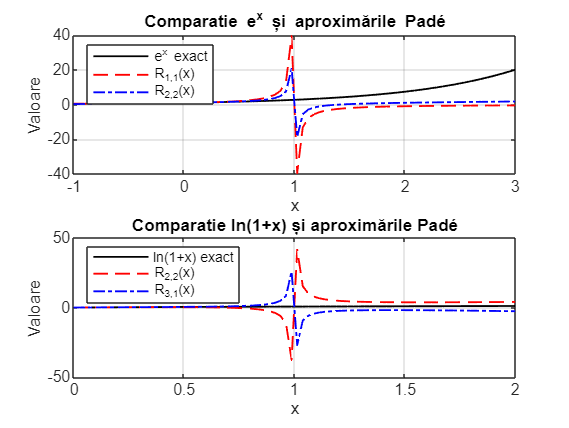

% Domeniul de reprezentare
x_exp = linspace(-1, 3, 80); % Pentru e^x
x_ln = linspace(0, 2, 80); % Pentru ln(1+x), evitând x ≤ -1

% Coeficienți Maclaurin pentru e^x
max_order = 6;
coeff_exp = zeros(1, max_order + 1);
for idx = 0:max_order
    coeff_exp(idx+1) = 1/factorial(idx);
end

% Aproximările Padé pentru e^x
[R11, a11, b11] = pade_approximation(coeff_exp,1,1,x_exp);
[R22, a22, b22] = pade_approximation(coeff_exp,2,2,x_exp);

% Plot comparativ e^x
figure;
subplot(2,1,1);
plot(x_exp, exp(x_exp), 'k', 'LineWidth', 1); hold on;
plot(x_exp, R11, '--r', 'LineWidth', 1);
plot(x_exp, R22, '-.b', 'LineWidth', 1);
% ylim([-2, 10]); 

legend('e^x exact', 'R_{1,1}(x)', 'R_{2,2}(x)', 'Location', 'NorthWest');
xlabel('x');
ylabel('Valoare');
title('Comparatie e^x și aproximările Padé');
grid on;

% Coeficienți Maclaurin pentru ln(1+x)
max_order = 6;
coeff_ln = zeros(1, max_order + 1);
for idx = 1:max_order  % ln(1+x) nu are termen constant
    coeff_ln(idx+1) = ((-1)^(idx+1)) / idx;
end

% Aproximările Padé pentru ln(1+x)
[R22_ln, a22_ln, b22_ln] = pade_approximation(coeff_ln,2,2,x_ln);
[R31_ln, a31_ln, b31_ln] = pade_approximation(coeff_ln,3,1,x_ln);

% Plot comparativ ln(1+x)
subplot(2,1,2);
plot(x_ln, log(1+x_ln), 'k', 'LineWidth', 1); hold on;
plot(x_ln, R22_ln, '--r', 'LineWidth', 1);
plot(x_ln, R31_ln, '-.b', 'LineWidth', 1);
% ylim([-2, 2]); 

legend('ln(1+x) exact', 'R_{2,2}(x)', 'R_{3,1}(x)', 'Location', 'NorthWest');
xlabel('x');
ylabel('Valoare');
title('Comparatie ln(1+x) și aproximările Padé');
grid on;